# Simulation 4 Companion

## Symbollically Executing Laplace Transforms

**Goal:** Use MATLAB to find a **formula **for the Laplace transform of $f(t) = te^t$ and then plot the result.

I want to find a formula for a Laplace transform. This is different from our earlier tasks, which did not provide formulas, but instead numerically computed a sequence of data points that we eventually plotted. 

If we want MATLAB to manipulate formulas and variables, then we need to use the [Symbolic Math Toolbox](https://www.mathworks.com/help/symbolic/index.html). First we define a [symbolic variable ](https://www.mathworks.com/help/releases/R2025a/symbolic/symbolic-variables-expressions-and-functions.html)`t` using `syms`. *You may need to install the Symbolic Math Toolbox. This can be done by following the instructions in MATLAB when you attempt to use *`syms`* without the addon.*

*Remember: uncomment the start of the line and hit run.*

syms t

Next we define the function $f(t) = te^t$ as a symbolic expression. Notice the left side is just the symbol `f` without the `(t)`. This is because I have chosen to treat $te^t$ as a **symbolic expression** as opposed to a **symbolic function** here.

f = t.*exp(t)

$$f = t\,{\mathrm{e}}^{t}$$

Then we use the [`laplace`](https://www.mathworks.com/help/symbolic/sym.laplace.html) function to execute the Laplace transform and we call the result $F$. By default the independendent symbolic variable of the result will be $s$.

F = laplace(f)

$$F = \frac{1}{{\left(s-1\right)}^{2}}$$

The output is a **symbolic expression**. It can be plotted using [`fplot`](https://www.mathworks.com/help/symbolic/fplot.html) which can plot symbolic expressions.

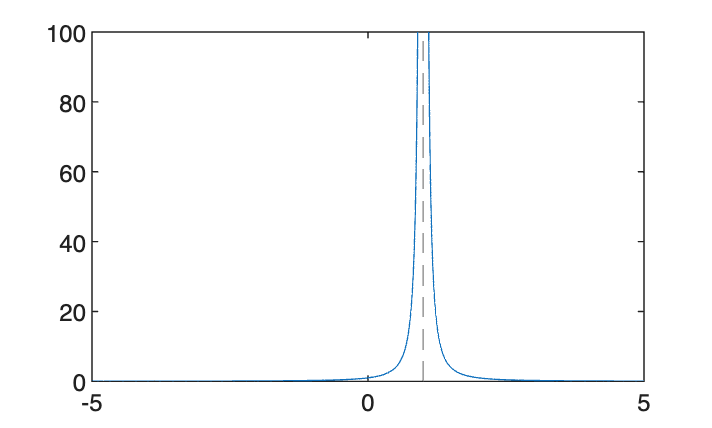

figure % new figure
fplot(F) % plot F and automatically create axes

## Numerically Approximating Laplace Transforms

**Goal: **Use MATLAB to **numerically approximate** the Laplace transform of $f(t) = e^{\sqrt{t}}$ at several values.

Sometimes there is not a simple formula for the Laplace transform, in which case the symbolic approach described in the previous section will fail. In this case we instead aim for a numerical approximation.

Remember that the Laplace transofm is an integral:


$$F(s) = \int_0^\infty e^{-st}f(t) \ dt$$


We will use MATLAB to numerically approximate this integral. MATLAB can have difficulty with $\infty$ bounds. So we use a change of variables to make the bounds finite. Let


$$u = e^{-t}$$
 

so that:


$$u(0) = 1$$



$$u(\infty) = 0$$


and:


$$t = - \ln u$$


and:


$$du = - e^{-t} dt = - u dt$$



$$dt = -\frac{du}{u}$$


Converting using this $u$-subtitution:


$$F(s) = \displaystyle \int_0^1 u^s f(- \ln u) \ \frac{du}{u}$$



$$F(s) = \int_0^1 u^{s-1}f(- \ln u) \ du$$


We have executed the mathematical setup preparing us to transition to MATLAB. This is the integral we will numerically approximate. 

Let us produce a function `laplaceNum` to do so. We use the [`integral`](https://www.mathworks.com/help/releases/R2025a/matlab/ref/integral.html) function as a component of our function.

*Note: no need to uncomment in the box below. Everything that needs to be uncommented already has been.*

%==========================================================================
%
% laplaceNum: Calculate a numerical approximation for the Laplace transform
% of f. Specically approximates the integral from 0 to 1 of u^(s-1)f(-ln(u))du.
%
%    laplaceNum(f)
%
%--------------------------------------------------------------------------
%
% ------
% INPUT:
% ------
%   f : (function_handle) f(t) to Laplace transform 
%
% ------
% Output:
% ------
%   F : (function_handle) Laplace transform F(s) of f(t) 
%
%==========================================================================

function F = laplaceNum(f)

% define the integrand u^(s-1)f(-ln(u)) as a function handle
integrand = @(s,u) u.^(s-1).*f(-log(u)) % log is the natural logarithm ln

% produce function handle F(s) as integral of integrand from 0 to 1
%   note: we are using the function integral(function_handle,lowerbound,upperbound)
%   note: we treat the integrand as a functon of u by writing @(u) integrand(s,u)
F = @(s) integral(@(u) integrand(s,u),0, 1)

end

Having created the `laplaceNum` function, let us clear all variables so they can be redefined as non-symbolic**.**

clear all % clear all variables

Next we define $f(t) = e^{\sqrt{t}}$ as a function handle.

f = @(t) exp(sqrt(t)) 

f = function_handle with value:
    @(t)exp(sqrt(t))


Now we compute the Laplace transform using our `laplaceNum` function.

F = laplaceNum(f)

integrand = function_handle with value:
    @(s,u)u.^(s-1).*f(-log(u))


F = function_handle with value:
    @(s)integral(@(u)integrand(s,u),0,1)


F = function_handle with value:
    @(s)integral(@(u)integrand(s,u),0,1)


Now I can evaluate the Laplace transform at various test values of `s`.

format long % output will be long decimals
F(1)

ans =    2.730234461467643


F(2)

ans =    0.991004373838521


F(5)

ans =    0.304010821281008


## Partial Fraction Decomposition

**Goal**: Use Matlab to execute the partial fraction decomposition of $F(s) = \frac{2s+7}{s^2+5s+6}$.

We can use the Symbolic Math Toolbox to execute partial fraction decompositions of symbolic expressions.

First let us clear all variables.

clear all % clear all variables

Next let us define the symbolic variable `s`.

syms s

And next define the symbolic expression $F = \frac{2s+7}{s^2+5s+6}$.

F = (2.*s+7)./(s.^2+5.*s+6)

$$F = \frac{2\,s+7}{s^{2}+5\,s+6}$$

And lastly use [`partfrac`](https://www.mathworks.com/help/releases/R2025a/symbolic/sym.partfrac.html) to execute the partial fraction decomposition.

F = partfrac(F)

$$F = \frac{3}{s+2}-\frac{1}{s+3}$$

Wow so pretty. If we want to pull out the summands of the decompsition we can use the [`children`](https://www.mathworks.com/help/releases/R2025a/symbolic/sym.children.html) function. It creates a [cell array](https://www.mathworks.com/help/releases/R2025a/matlab/ref/cell.html) of the summands. 

children(F)

ans = 1×2 cell array
    {[3/(s + 2)]}    {[-1/(s + 3)]}


To access components in this array you can use `children(F,index)`

children(F,1)

$$ans = \frac{3}{s+2}$$

children(F,2)

$$ans = -\frac{1}{s+3}$$

If I like I can plot $F$ and its children $F_1$ and $F_2$ on a single set of axes.This provies a visual represnetation of $F = F_1+F_2$.

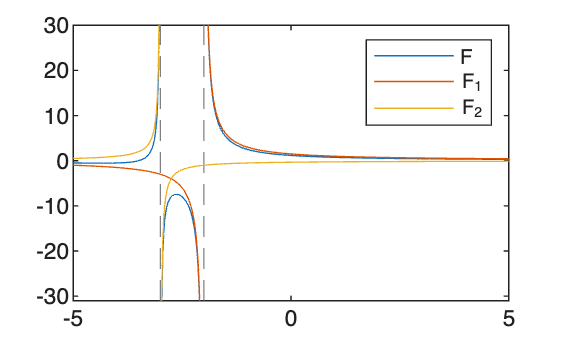

figure % new figure
fplot(F) % plot F
hold on
fplot(children(F,1)) % plot F_1
hold on
fplot(children(F,2)) % plot F_2
legend("F","F_1","F_2") % label F, F_1, F_2